# Main Results 

This file contains the main results discussed in [Section, Paper]. 

#### Pulse Approximation 

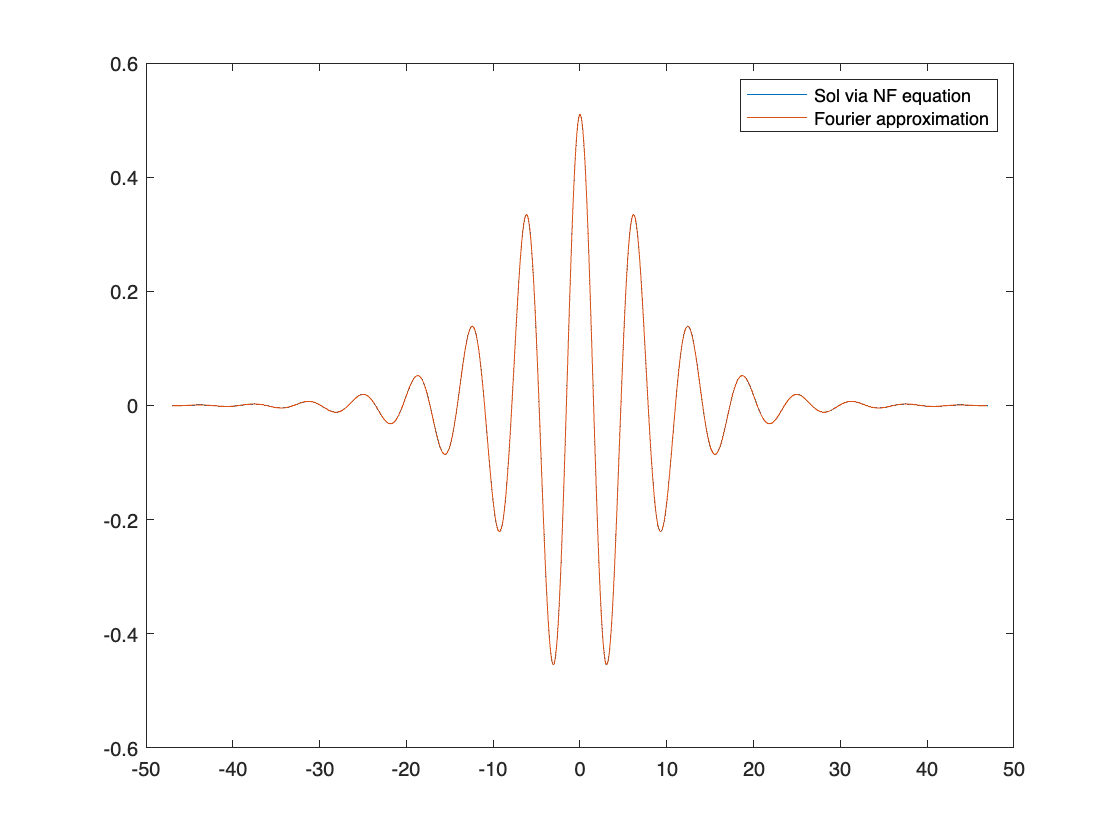

order = 200;
params.nu = 1.2;
params.mu = .1;
vfParams = params;
nfBranch = 0; 
time = 50; 


S = PulseSolution(order, vfParams, nfBranch, time);
S = S.BKNormalForm4dim();
S = S.trimNFSol();
S = S.getFullFourierCoeffs();

fun = S.getFunctionFromFourierCoeffs();

time = S.nfData.time; 
sol = S.nfData.sol(:,1);
figure
plot(time, sol);
hold on
plot(fun(:,1),fun(:,2))
legend('Sol via NF equation','Fourier approximation')


S= S.NewtonFourierNDBC()

Error using  / 
Matrix dimensions must agree.
Error in PulseSolution/NewtonFourierNDBC (line 16)
        s = s - DF/(fcn');


DF=S.DFFourier();

[V,D]=eig(DF);
[i,j] = find(D>0);
if min(size(D(i,j))) == 1
    disp(D(i,j));
else 
    A = D(i,j);
    disp(A)
end